# MTHE 393 Example: Finding a Transfer Function from Bode Plot

**Copyright (c) 2019 by Scott Kyle**

This is an example of estimating a transfer function from a Bode Plot.

## Define a Transfer Function

% Clear the workspace

% Define a test system (we need to do this to do anything useful)
% Use the ZPK format. We have to pretend we don't know this exists.

sys1 = zpk ([10^(-2) -10^0 10^(1.3)],[-10^(-1.2) -10^(1.5) -10^(2) -10^(3)],[10000]);

% Note: we have 3 zeros (2 unstable i.e. in RHP), and 4 poles (all stable i.e. in LHP).
% clear variables;

## Create a Bode Plot of this Function so we can analyze it

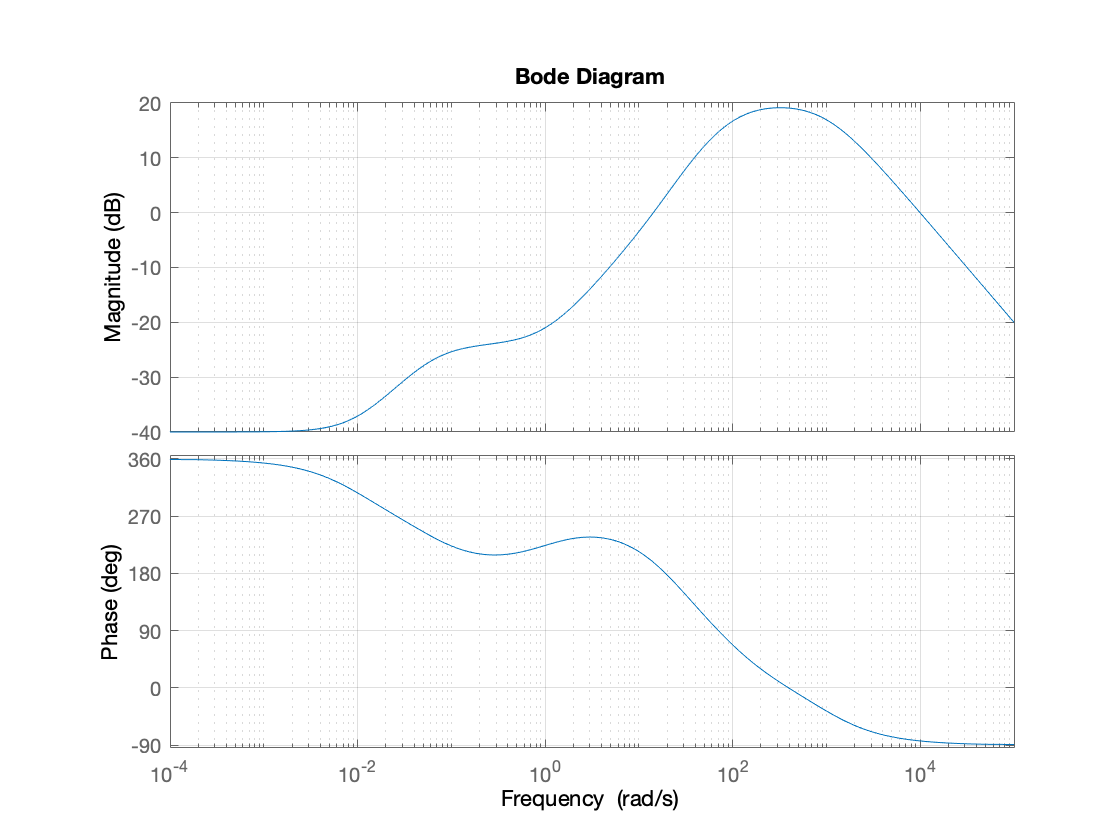

% Create Bode Plot
figure(1)
bode(sys1)

grid on

## Determine Certain Features

% What is the slope (roll-off) at high frequencies?

% slope = -20; % dB/dec

% What does this indicate? Note: -20*n is roll-off where n = Np - Nz
% Np is number of poles.
% Nz is number of zeros.
% We know n=1.

% Look at "critical points" on magnitude plot to determine corner frequencies.

% Estimate zeros

% Zeros [essentially where there is an "increase in slope"]

z1 = 10^(-2);
z2 = 10^(0);
% z3 = 10^();
% z4 = 10^();
% z5 = 10^();

% Poles [essentially where there is a "decrease in slope"]

p1 = 10^(-1);
p2 = 10^(2);
p3 = 10^(2.8);
% p4 = 10^();
% p5 = 10^();
% p6 = 10^()s;

## Plot Estimate of Bode Plot Using Initial Zeros and Poles

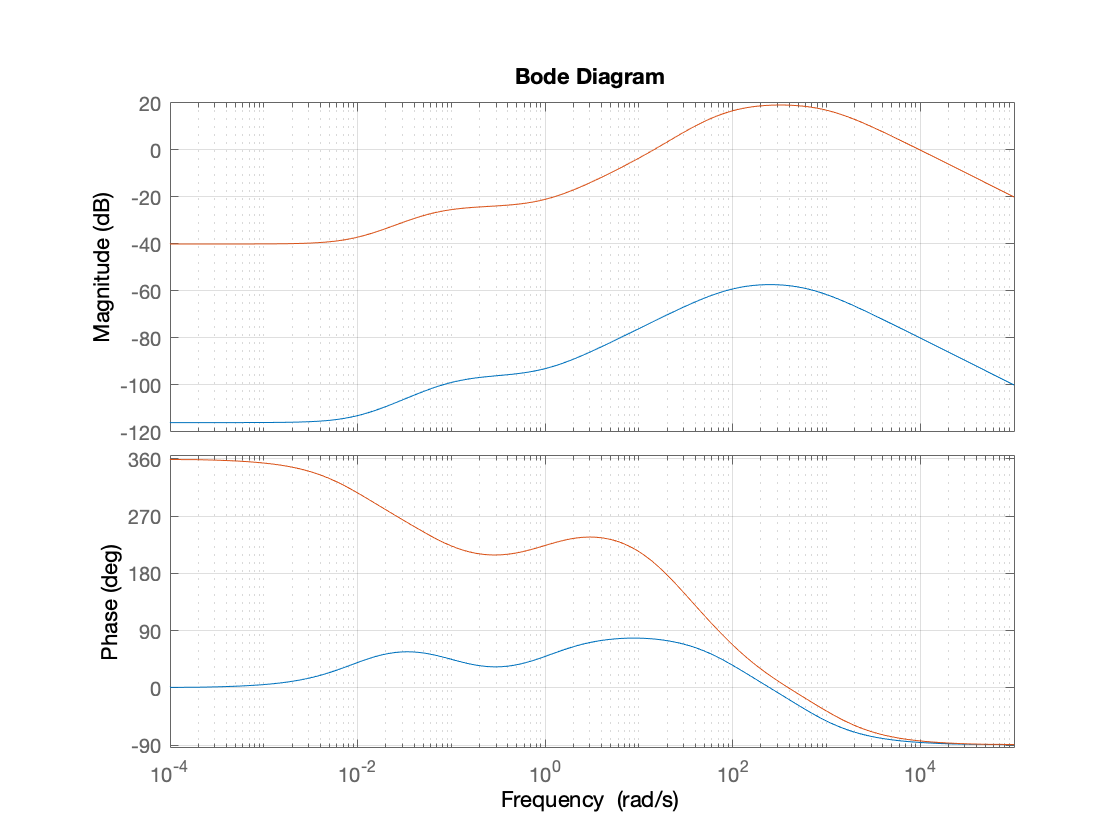

% Use zero and pole values from above

% Assume all poles (valid) and zeros (uncertain) are stable and hence lie in
% the LHCP. Choose a gain (K) of 1 to begin with.

sys = zpk([-z1 -z2],[-p1 -p2 -p3],[1]);
figure(2)
bode(sys,sys1)
grid on

## Figure out K

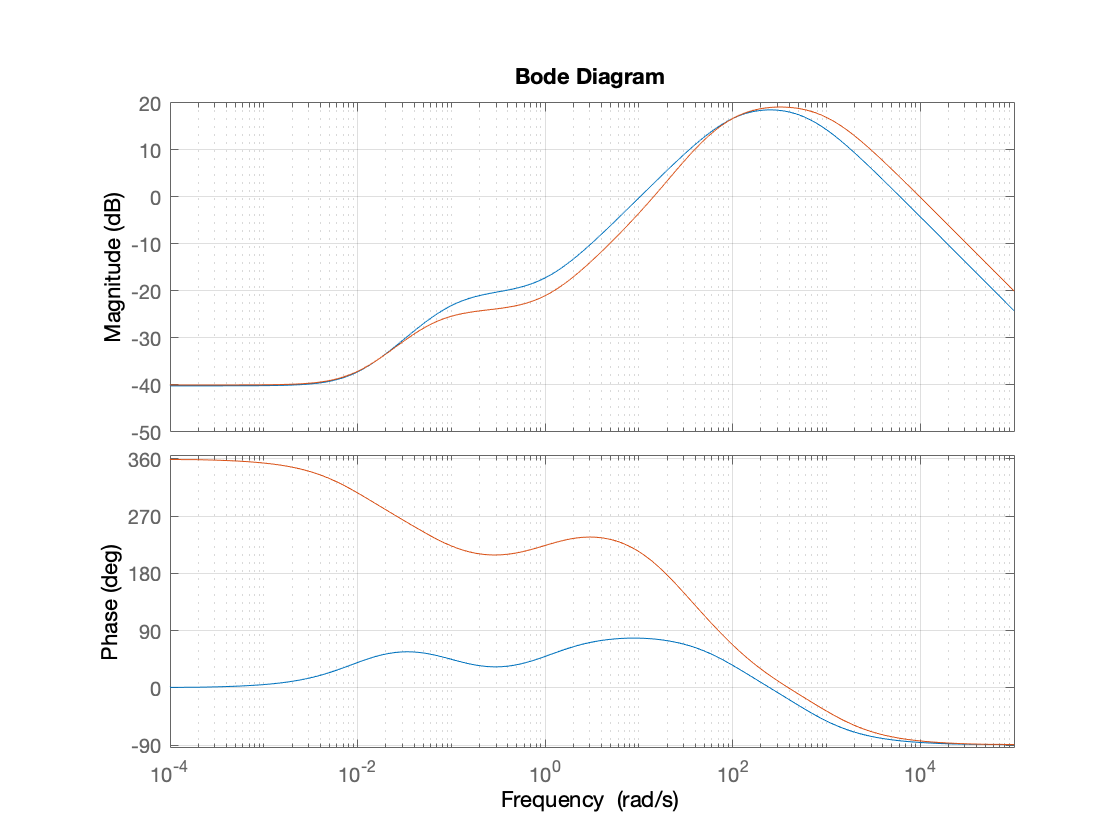

% We know we can simply shift the Bode Plot by altering our gain.

% The difference in this case is ~80 db.

% Calculate this (or do it by hand)

M1 = evalfr(sys1,10^(-4));
M = evalfr(sys,10^(-4));

delta = 20*log10(M1)-20*log10(M);

K = 10^(delta/20); %

sys = zpk([-z1 -z2],[-p1 -p2 -p3],[K]);

% Compare Plots
figure(3)

bode(sys,sys1)
grid on

## Out by 360 degrees?

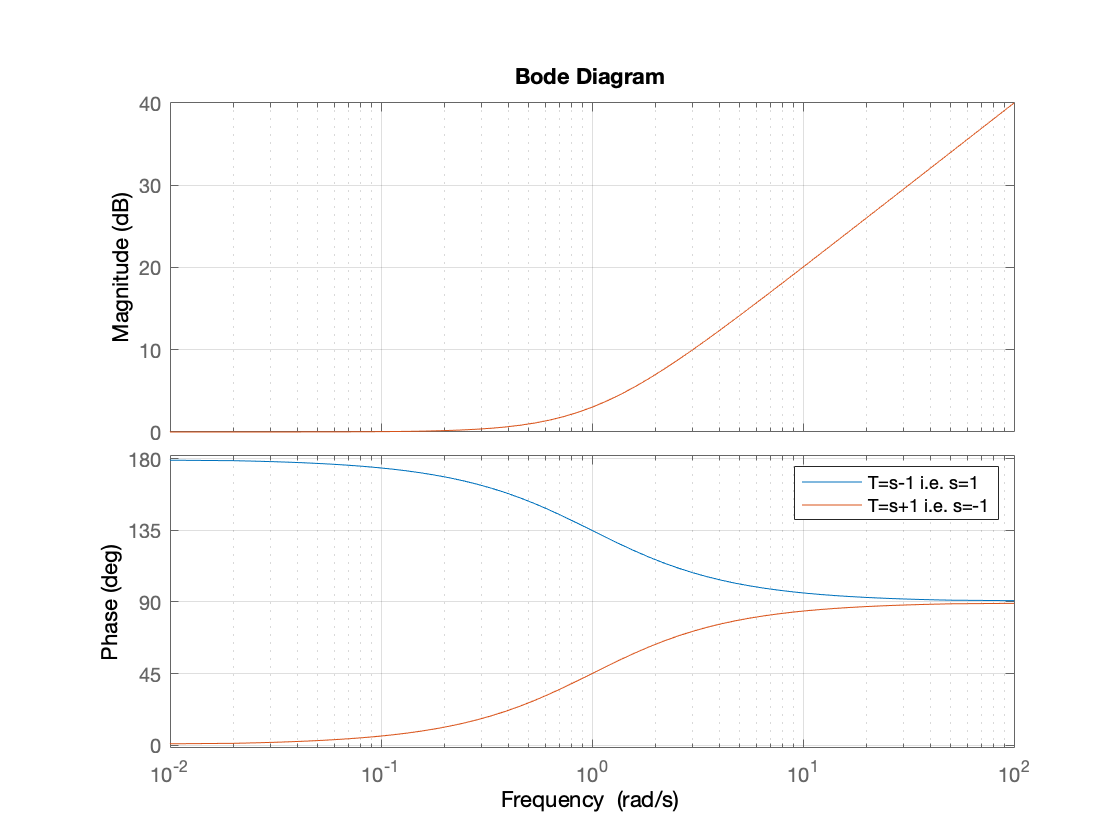

% It looks like we are out by 360 degrees.

% What might be the cause of this? 

% How do zeros contribute phase?

zero1 = zpk([1],[],[1]);
zero2 = zpk([-1],[],[1]);
figure()
bode(zero1,zero2)
grid on
legend('T=s-1 i.e. s=1','T=s+1 i.e. s=-1')

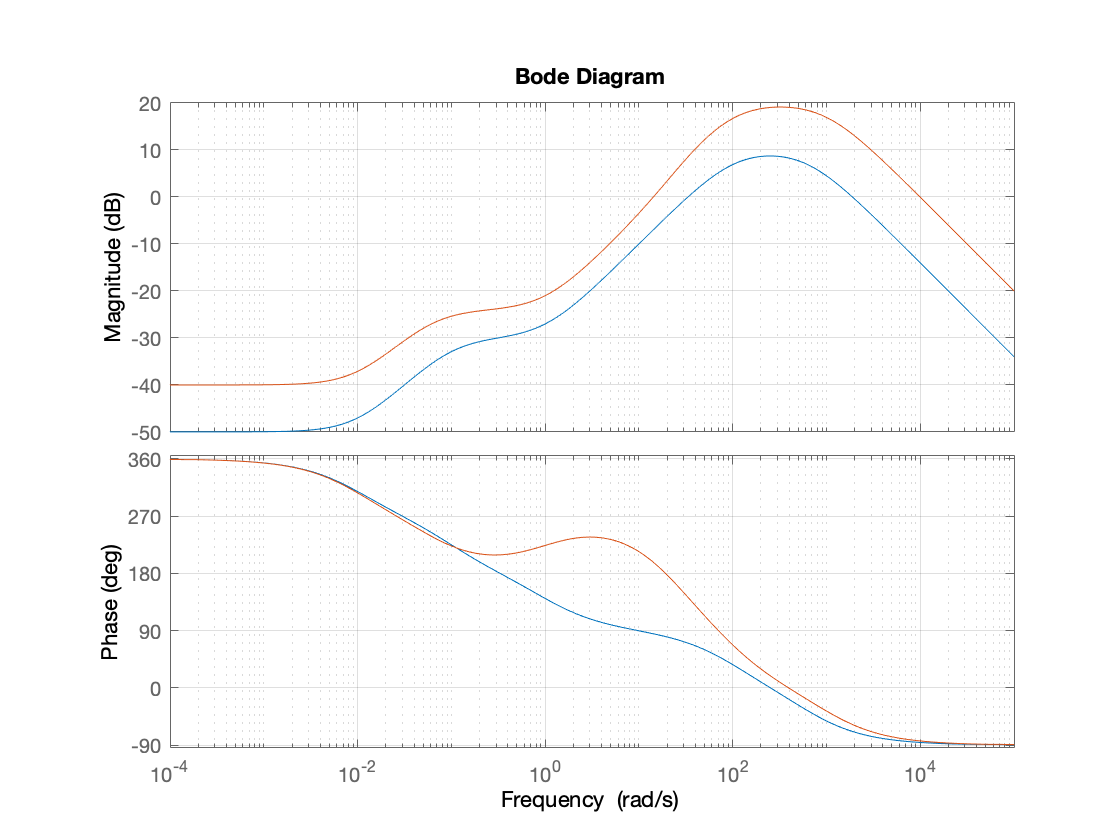


% Evidently, magnitude plots are the same. This makes sense.

% At high frequencies, phase contribution is 90 degrees. But at low frequences, they have the same magnitude, 
% but different phase (out by 180 degrees). Why?

% Run a lttile simulation as to why this is the case... need to open a new figure.
% Go to ZeroMagnitudePhase.m file.


% If they are RHP plane zeros, they add ZERO phase at small frequencies, instead of 180 degrees each. 360 / 180 
% means two zeros live in the RHP. Therefore, change their signs. Note, it is confirmed we have 2 RHP zeros, but
% they are not necessarily these two (if we find more).

sys = zpk([z1 z2],[-p1 -p2 -p3],[K]);

% Compare Plots
figure(5)
bode(sys,sys1)
grid on

## Determine what is going on in the middle?

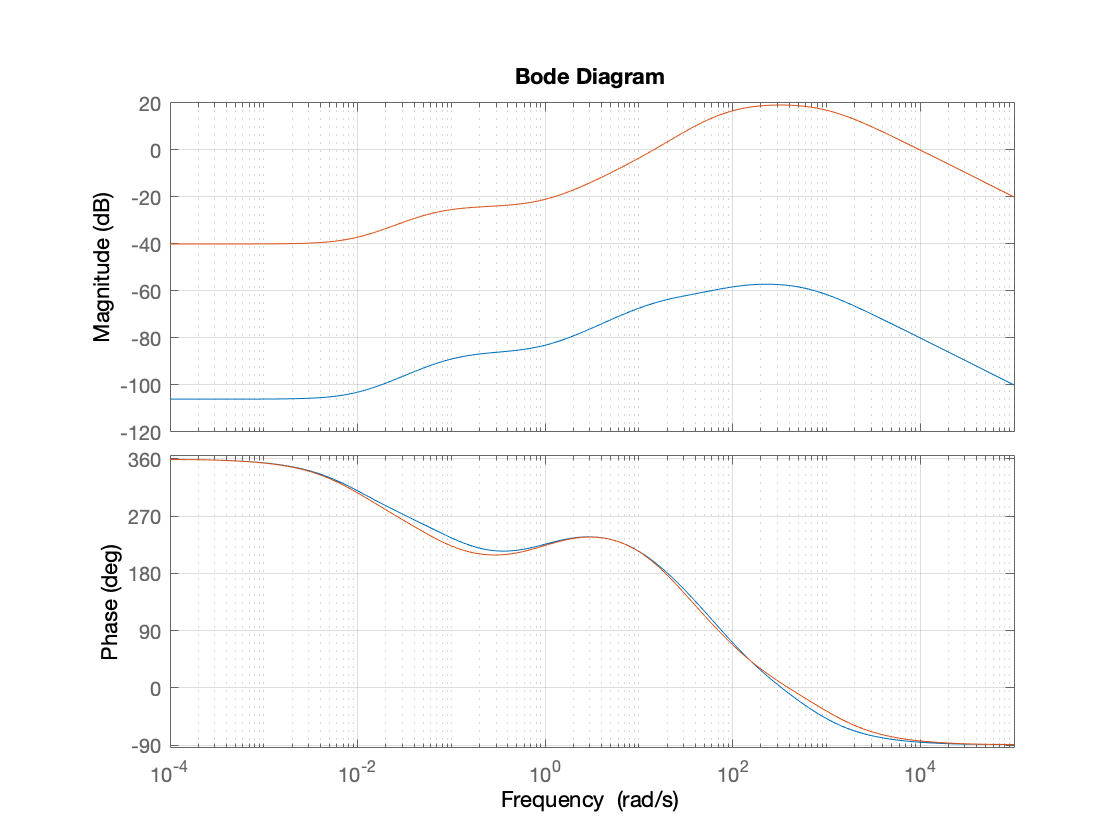

% It looks like there are additional dynamics we need to consider between 10^(-1) and 10^2.
% From the plot it looks like we are ADDING and SUBTRACTING PHASE at some point.

% We know all the poles are stable, and therefore the pole is removing phase. 
% Identify where this is happening

p4 = 10^(1.2); % Read this off the graph;

% We can infer from the plot the the zero is adding phase just after this pole, (around 100 rad/s). 
% This is a bit of a guess, but we know we are out 180 degrees of phase at omega = 50, so need add
% 180 degrees of phase here (what kind of zero is this?!!)

z3 = 50; 

% Try the new sys. Reset K to 1 and we will calibrate again afterwards.

sys = zpk([z1 -z2 z3],[-p1 -p2 -p3 -p4],[1]);

% Compare Plots
figure(6)
bode(sys,sys1)

grid on


% Remember, that 2 poles are in the RHP (as this is the only way to get 360 degrees
% of phase at low frequencies),and one of them IS z3. So need to try other two zeros
% and see if plots match.


## Determine K again

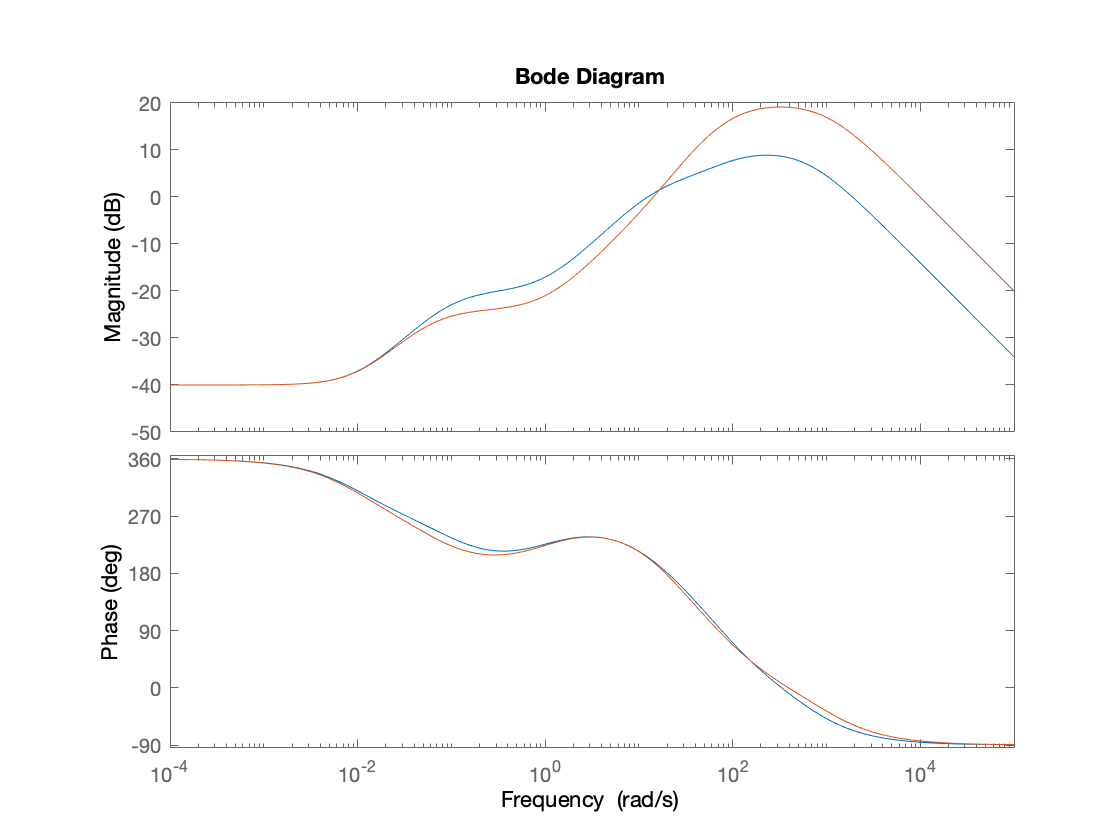

% We know we can simply shift the Bode Plot by altering our gain

% Calculate this (or do it by hand)

M1 = evalfr(sys1,10^(-4));
M = evalfr(sys,10^(-4));

delta = 20*log10(M1)-20*log10(M);

K = 10^(delta/20); %

sys = zpk([z1 -z2 z3],[-p1 -p2 -p3 -p4],[K]);

% Compare Plots
bode(sys,sys1)

## Conclusion

% By no means is the Bode Plot on the right perfect, but it is a working transfer function that exhibits
% the characterisitcs of the original system.

% You can fine-tune the location of the poles and zeros accordingly to match it "perfectly".


## Another way to validate your transfer function (compare step functions)

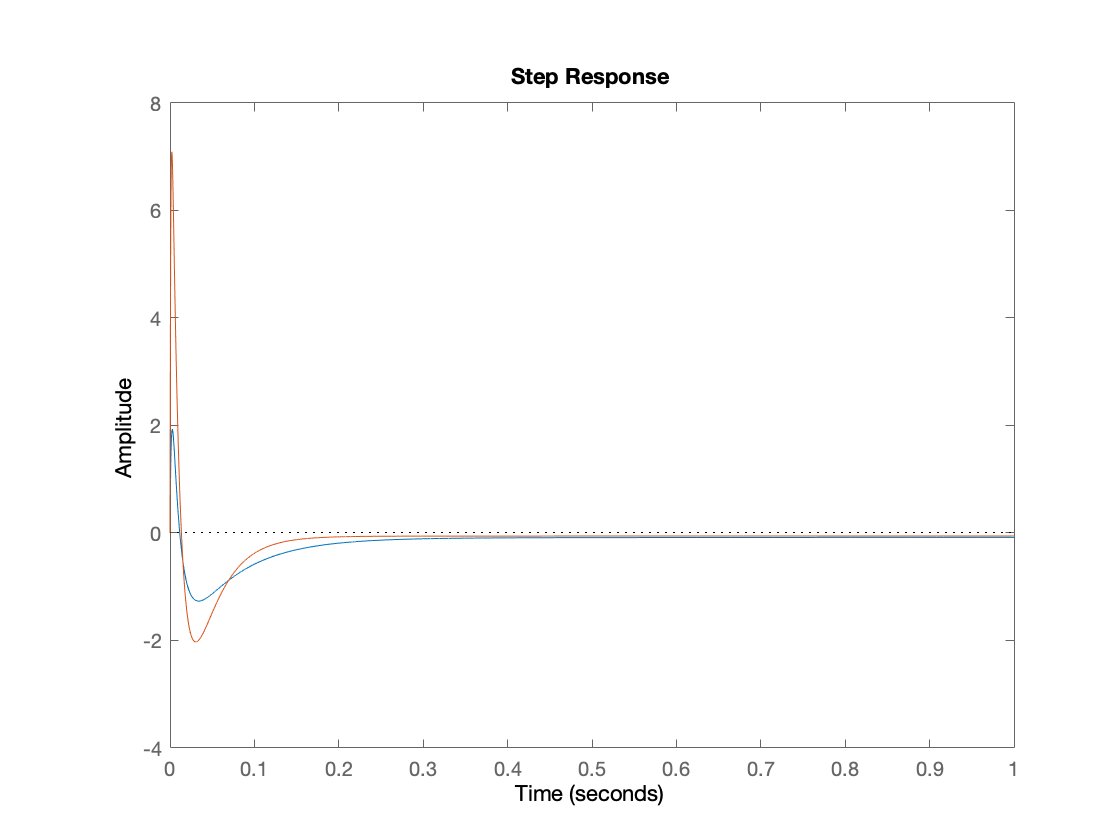

% Compare Step Functions

step(sys,sys1,1)


% So it is obvious we need to modify the locations of some poles and/or zeros.



